# Plotting bathymetry

This guide illustrates how to plot bathymetry data.

## Plotting cell-wise bathymetry

There are a few plotting options for bathymetry. This guide assumes a project is already instantiated in the `project` variable. The bathymetry object can be retrieved from the project.

bathy = project.bathymetry

bathy =   BathymetryFile with properties:

    GridgenBathymetryFile: [0×0 AutoDepomod.BathymetryFile]
        GridgenDomainFile: [0×0 AutoDepomod.DomainFile]
                     data: [79×79 double]
                     path: 'C:\newdepomod_projects\bay_of_fish\depomod\bathymetry\bay_of_fish.depomodbathymetryproperties'
                   Domain: [1×1 struct]
          endOfDataMarker: 'endOfDataMarker'
        startOfDataMarker: 'startOfDataMarker'

The raw, cell-by-cell water depth values can be plotted easily

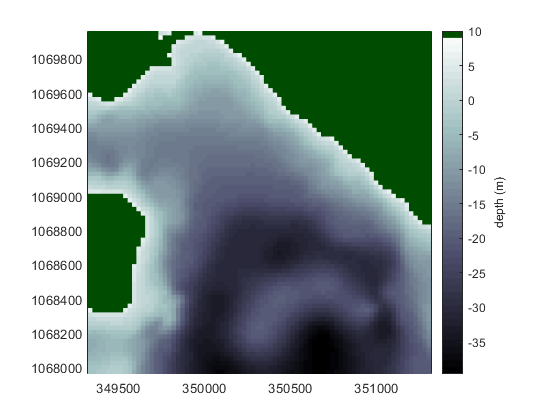

figure;
bathy.plot

## Plotting bathymetry contours

Alternatively, water depths can be described by contours

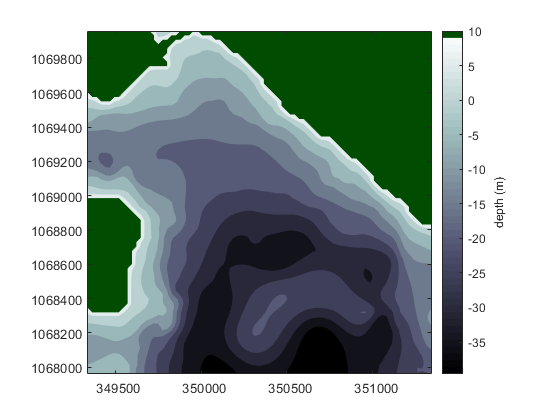

figure;
bathy.plot('contour',1)

In either case a handle to the resulting plot can be outputted to a variable, i.e.

H = bathy.plot('contour',1)